# Exploring face stimuli

## Load 2 face images

prjDir = fullfile('/Volumes', 'server', 'Projects', 'TemporalPsychophysics');

% prjDir = tPsychophysicsRootPath;

imgDir = fullfile(prjDir, 'stimulus', 'Images', 'chosenMaskedFaceStimulus');

img{1} = imread(fullfile(imgDir, 'chosenMaskedface3.png'));
img{2} = imread(fullfile(imgDir, 'chosenMaskedface4.png'));

## Cut the original images

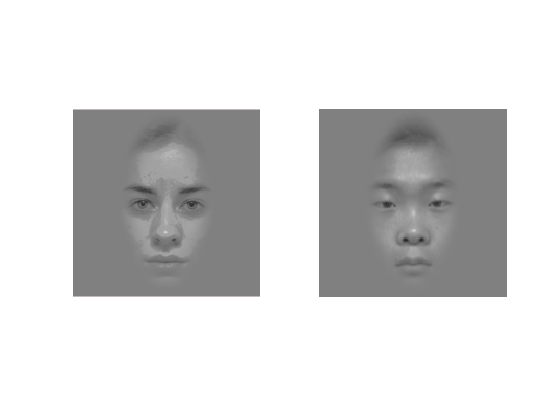

cuttedEdge = 38; % number of pixels
imgLth     = length(img{1});
for k = 1 : 2
    nimg{k} = img{k}(cuttedEdge + 1: imgLth - cuttedEdge, cuttedEdge + 1: imgLth - cuttedEdge);
end
nimgLth = length(nimg{1});

figure, for k = 1 : 2, subplot(1, 2, k), imshow(nimg{k}); end

## Cut image into squares of different sizes

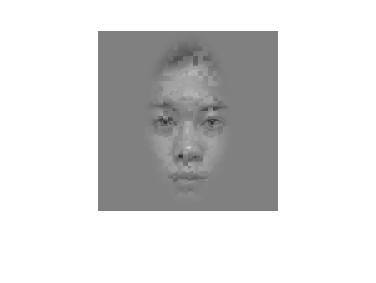

gridSz  = 5; % in unit of pixels
nGrid   = ceil(nimgLth/gridSz);
newImg1 = cell(1, 2);
newImg2 = size(newImg1);
clear tmp newImg1 xpixels ypixels

groupPxls = @(x, y) (x - 1) * y + 1 : x * y;
mkOrder   = @(n) randi([1, 2], n, n);

 order = mkOrder(nGrid);

for nImgs = 1 : 5
for iGrid1 = 1 : nGrid % x -axis
   for iGrid2 = 1 : nGrid % y-axis
       xpixels = groupPxls(iGrid1, gridSz);
       ypixels = groupPxls(iGrid2, gridSz);
       
       tmp{iGrid1, iGrid2} = nimg{order(iGrid1, iGrid2)}(xpixels, ypixels);
       
   end
end
end
newImg1{1} = cell2mat(tmp);
figure
imshow(newImg1{1})